## **Group Members**


p1 = {'givenName', 'surNAme', 'matriculationNumber'};
p2 = {'givenName', 'surNAme', 'matriculationNumber'};
p3 = {'givenName', 'surNAme', 'matriculationNumber'};
p4 = {'givenName', 'surNAme', 'matriculationNumber'};

Members = {'p1'; 'p2'; 'p3'; 'p4'};
GivenNames = {'Matsimbo Fotsing'; 'Tsiegoum Mouafo'; 'Dongmo Kingni Diffo'; 'Henschel'};
SurNames = {'Cecile Darelle'; 'Naomi Ghislaine'; 'Vianey'; 'Leuwaing Forsuh'};
MatriculationNumbers = {'3222693'; '3199972'; '3200261'; '3186914'};

groupTable = table(Members, GivenNames, SurNames, MatriculationNumbers);
disp(groupTable)

    Members          GivenNames                SurNames          MatriculationNumbers
    _______    _______________________    ___________________    ____________________

    {'p1'}     {'Matsimbo Fotsing'   }    {'Cecile Darelle' }        {'3222693'}     
    {'p2'}     {'Tsiegoum Mouafo'    }    {'Naomi Ghislaine'}        {'3199972'}     
    {'p3'}     {'Dongmo Kingni Diffo'}    {'Vianey'         }        {'3200261'}     
    {'p4'}     {'Henschel'           }    {'Leuwaing Forsuh'}        {'3186914'}     



# **Computer Based Engineering Mathematics**

#### `Lab Project`

#### **Project 2: It's all about the Primes**

#### *Introduction*

A prime number is a natural number greater than 1 that cannot be expressed as the product of two smaller natural numbers. In other words,* it has no divisors other than 1 and itself*. Natural numbers greater than 1 that are not prime are called *composite numbers*, as they can be written as the product of smaller natural numbers. A divisor of a number is any natural number that divides it exactly, leaving no remainder. Every natural number has at least two divisors, that is 1 and the number itself, but prime numbers have no other divisors besides these two.

# **Task 1**: RSA cryptosystem and prime numbers

## Prime Numbers & RSA Crytosystem

The **RSA** (**Rivest–Shamir–Adleman**) **cryptosystem** is a [public-key cryptosystem](https://en.wikipedia.org/wiki/Public-key_cryptography), one of the oldest widely used for secure data transmission that is, it enables secure digital communication without needing to share private keys in advance.. The [initialism](https://en.wikipedia.org/wiki/Initialism) "RSA" comes from the surnames of [Ron Rivest](https://en.wikipedia.org/wiki/Ron_Rivest), [Adi Shamir](https://en.wikipedia.org/wiki/Adi_Shamir) and [Leonard Adleman](https://en.wikipedia.org/wiki/Leonard_Adleman), who publicly described the algorithm in 1977.

# **Task 2**: Two prime number-related functions

function v= firstNprimeNumbers(n)
    if n<1
        error('n must be a positive integer');
    end
    
    v= zeros(1,n);
    count=0;
    cand=2; %current candidate interger
    
    while count<n
        if IsPrime(cand)
        count=count+1;
        v(count)=cand;
        end
      cand=cand+1;
    end
    
    end


function tf = IsPrime(n)
% isPrimeNumber  Returns true if n is prime, false otherwise.
%
%   tf = isPrimeNumber(n) returns a logical 1 (true) if n is a prime
%   integer ≥ 2, and 0 (false) otherwise.

    % Handle non-integers, n < 2, etc.
    if ~isscalar(n) || n ~= floor(n) || n < 2
        tf = false;
        return;
    end

    % 2 is prime
    if n == 2
        tf = true;
        return;
    end

    % eliminate even numbers > 2
    if mod(n,2) == 0
        tf = false;
        return;
    end

    % trial division up to sqrt(n), checking only odd divisors
    r = floor(sqrt(n));
    for k = 3:2:r
        if mod(n,k) == 0
            tf = false;
            return;
        end
    end

    % if no divisor found, it’s prime
    tf = true;
end
%% 
function tf = IsPrimeNum(n)
% isPrimeNumber  Returns true if n is prime, false otherwise.
%
%   tf = isPrimeNumber(n) returns a logical 1 (true) if n is a prime
%   integer ≥ 2, and 0 (false) otherwise.

    % Handle n < 2
    if  n < 2
        tf = false;
        return;
    end
    % trial division up to sqrt(n), checking only odd divisors
    for k = 2:n-1
        if mod(n,k) == 0
            tf = false;
            return;
        end
    end

    % if no divisor found, it’s prime
    tf = true;
end




%% sum of all primes below n:  test with unoptimised IsPrime
function s = sumPrimesBelow(N)
    if N < 2   %avoid code crashing when n<1
        s = 0;
        return;
    end
    s = 0;
    for cand = 2 : N
        if IsPrimeNum(cand)
            s = s + cand;
        end
    end
end
n=1.5e6;
tic;
sum=sumPrimesBelow(n);
elapsed = toc;
fprintf('sum of primes < %.0f is %.0f\n',n,sum);

sum of primes < 1500000 is 82074443256


fprintf('Elapsed time: %.3f seconds\n', elapsed);

Elapsed time: 1302.337 seconds


%% test with optimised IsPrime
function s = improvedSumPrimesBelow(N)
    if N < 2
        s = 0;
        return;
    end
    s = 0;
    for cand = 2 : N
        if IsPrime(cand)
            s = s + cand;
        end
    end
end
n=1.5e6;
tic;
sum=improvedSumPrimesBelow(n);
elapsed = toc;
fprintf('sum of primes < %.0f is %.0f\n',n,sum);

sum of primes < 1500000 is 82074443256


fprintf('Elapsed time: %.3f seconds\n', elapsed);

Elapsed time: 4.298 seconds


%% 
x=firstNprimeNumbers(5);
disp(x)

     2     3     5     7    11




%% Task 4.1
function p= pie(v)
    p=0;
    for i=2:v
        if(IsPrimeNum(i))
            p=p+1;
        end
    end
end
x=(10:10:100);
y=zeros(1,length(x));
for i= 1:length(x)
       y(i)=pie(x(i)); 
end

disp(y)

     4     8    10    12    15    17    19    22    24    25



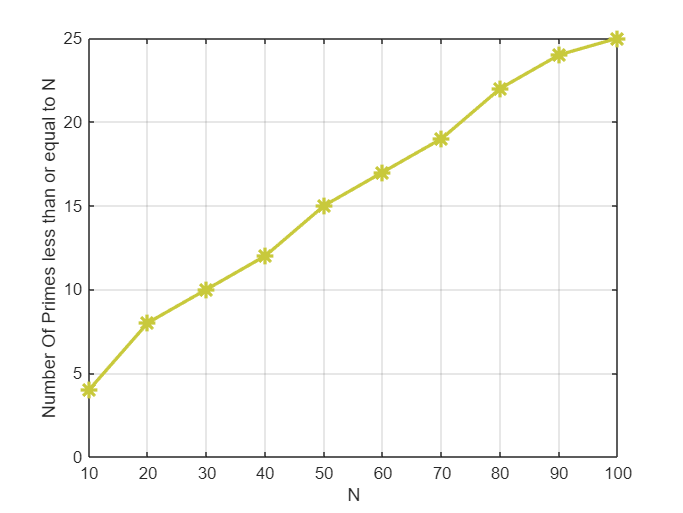


p=plot(x,y);
%%title("Graph of prime-counting function pie(x)");
xlabel('N')
ylabel("Number Of Primes less than or equal to N")

p.LineWidth = 2;
p.Color = [200/255 201/255 60/255];
p.Marker = "*";
p.MarkerSize = 10; 
grid on;

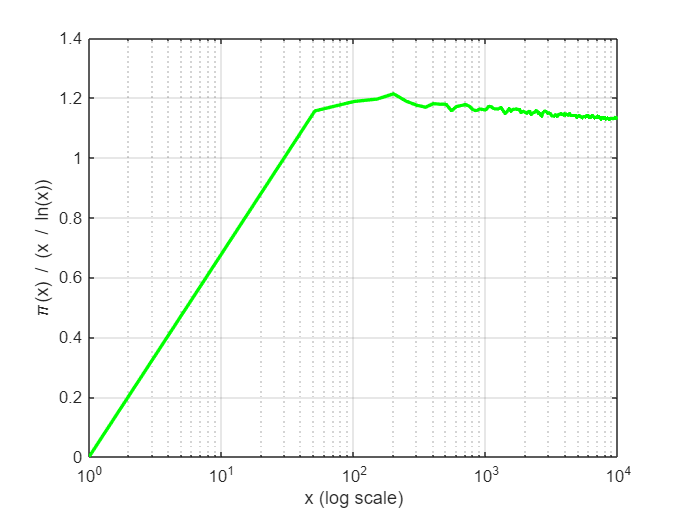


%% Task 4.2
x_max = 1e4;

% claculating pie_x for some x values

x_values = 1:50:x_max;
pie_x=zeros(1,length(x_values));
for i= 1:length(x_values)
       pie_x(i)=pie(x_values(i)); 
end

% calculating x/lnx(approx_values) for these same x values

approx_values = x_values ./ log(x_values);

% calculating ratio (pie_x/approx_values) 

ratio = pie_x ./ approx_values;

%plotting

semilogx(x_values,ratio,'g-', 'LineWidth', 2)
xlabel('x (log scale)');
ylabel('\pi(x) / (x / ln(x))');
grid on;


%% with log space
x_max = 1e4;

% claculating pie_x for some x values

x_values = logspace(1,5,400);
pie_x=zeros(1,length(x_values));
for i= 1:length(x_values)
       pie_x(i)=sum(isprime(1:floor(x_values(i)))); 
end

The logical indices contain a true value outside of the array bounds.


% calculating x/lnx(approx_values) for these same x values

approx_values = x_values ./ log(x_values);

% calculating ratio (pie_x/approx_values) 

ratio = pie_x ./ approx_values;

%plotting

semilogx(x_values,ratio,'g-', 'LineWidth', 2)
xlabel('x (log scale)');
ylabel('\pi(x) / (x / ln(x))');
grid on;



%% Task 5 optimised
function prime_max = lazyLargestPrimeFactor(N)
    prime_max=0;
    for i= 2:floor(sqrt(N))
        while mod(N,i) == 0 && IsPrimeNum(i)
            prime_max = i;
            N = N / i;
        end
    end
    if N > 1 % because else p_max will correctly hold the largest prime factor found.
        prime_max = N;
    end
end
p1=lazyLargestPrimeFactor(2287946);
p2=lazyLargestPrimeFactor(565499313531);
disp(p1)
disp(p2)
